# Taller XIII

### 26/06/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 12 y 13*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas sobre la teoria:*

`Algunas ecuaciones de avance para los métodos númericos son:`

- `Euler`

  

- `Taylor orden M`

- `Euler Modificado`

- `Heun`

        

- `Runge-Kutta orden 4`

        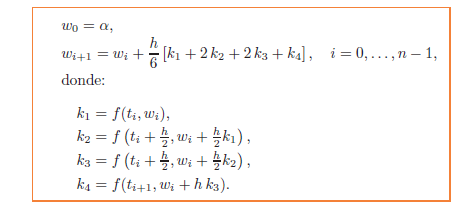

- `Diferencias finitas centradas`

     

- `Diferencias finitas en ecuaciones diferenciales parciales`

   

`El método de disparo lineal, recordar que se realiza la transformación de EDO con condiciones Dirichlet a un sistema Cauchy`

`Con solución:`

*Notas sobre los métodos:*

**    Solución Númerica de ecuaciones diferenciales:**

`R = rk4 (f, a, b, ya, M)`` : La versión multivariada es` `rks4`

`        - f funcion creada con @`

`        - a y b son los extremos izquierdo y derecho`

`        - ya es la condicion inicial  y(a)`

`        - M es el numero de pasos`

`        - R = [T', Y'] donde  T  es el vector de abscisas`

`            y  Y  es el vector de ordenadas`

`L = linsht (F1, F2, a, b, alpha, beta, M)`

                `- F1 y F2 son los sistemas de ecuaciones de primer orden`

                `    representando los Problemas de Valor Inicial (P.V.I.'s)`

                `    (9) and (10), respectivamente; funciones creadas con @`

                `- a y b son los extremos del intervalo`

                `- alpha = x(a)  y  beta = x(b); las condiciones frontera`

                `- M es el numero de pasos`

                `- L = [T', X]; donde  T' es el vector de abscisas (M+1) x 1`

                `    y  X  es el vector de ordenadas  (M+1) x 1`

`F = findiff (p, q, r, a, b, alpha, beta, N)`

                `- p, q, r  son las funciones coeficientes de`

                `    f(t,x,x')=p(t)x'+q(t)x+r(t) introducidas con @`

                `- a y b son los extremos izquierdo y derecho`

                `- alpha = x(a)  y  beta = x(b)`

                `- N es el numero de pasos`

                `- F = [T', X']: donde T' es el vector de abscisas  1 x N  y`

                `    X' es el vector de ordenadas  1 x N.`

`U = poisson(g,f1,f2,f3,f4,a,b,c,d,m,n)`

`poisson.m  -- Resuelve el problema de Poisson u_{xx} + u_{yy} = g(x,y)`

`en [a,b] x [c,d], usando el metodo de diferencias finitas de cinco puntos`

`        - g funcion creada con @`

                `- f1 es la condicion de frontera abajo (en y=c) funcion creada con @`

                `- f2 es la condicion de frontera derecha (en x=b) funcion creada con @`

                `- f3 es la condicion de frontera arriba (en y=d) funcion creada con @`

                `- f4 es la condicion de frontera izquierda (en x=a) funcion creada con @`

                `    Las funciones f1, f2, f3 y f4 se ingresan como cadenas de carateres`

                `- m es el numero de puntos sobre el eje x`

                `- n es el numero de puntos sobre el eje y`

### Solución númerica de ecuaciones diferenciales parciales

#### Problemas elípticos en un rectángulo

Para el taller de esta semana se solucionan tres ejercicios: $\left.\left.\left.1\right),4\right),\&\;7\right)$ del taller 14

**1. **Se propone el problema $\nabla^2 u=0$ en el rectángulo $R=\left\lbrace \left(x,y\right)\;/\;0<x<1,0<y<1\right\rbrace$ con condiciones de borde obtenidas de la solución exacta, la cual es $g\left(x,y\right)=\textrm{xy}$. Por tanto:

$u\left(x,0\right)=0:0\le x\le 1$, $u\left(x,1\right)=x:0\le x\le 1$

$u\left(0,y\right)=0:0\le y\le 1$, $u\left(1,y\right)=y:0\le y\le 1$

`No se hizo taller, se hizo review`

**4. **Se propone el problema $\nabla^2 u=4$ en el rectángulo $R=\left\lbrace \left(x,y\right)\;/\;0<x<1,0<y<2\right\rbrace$ con condiciones de borde obtenidas de la solución exacta, la cual es $g\left(x,y\right)={\left(x-y\right)}^2$. Por tanto:

$u\left(x,0\right)=\;:0\le x\le 1$, $u\left(x,2\right)=\;:0\le x\le 1$

$u\left(0,y\right)=\;:0\le y\le 2$, $u\left(1,y\right)=\;:0\le y\le 2$

`No se hizo taller, se hizo review`

**7. **Una placa rectangular de plata de $6-\textrm{cm}\times \;5-\textrm{cm}$ tiene una distribución de temperatura debida a que en cada punto hay calor uniformemente generado a una rata $q=1\ldotp 5\;\textrm{cal}/{\textrm{cm}}^3 \cdot s$. Sea $x$ a lo largo del borde de $6\;\textrm{cm}$ y $y$ la distancia a lo largo del borde de $5\;\textrm{cm}$. La temperatura en los bordes

están dadas por las siguientes funciones:

$u\left(x,0\right)=\;:0\le x\le 6$, $u\left(x,5\right)=\;:0\le x\le 6$

$u\left(0,y\right)=\;:0\le y\le 5$, $u\left(6,y\right)=\;:0\le y\le 5$

donde el origen $\left(0,0\right)$ es la esquina inferior izquierda de la placa. La temperatura de estado estacionario $u\left(x,y\right)$ satisface la ecuación de Poisson


$$\frac{\partial^2 u}{\partial x^2 }\;+\frac{\partial^2 u}{\partial y^2 }=-\frac{q}{K}:0<x<6,\;0<y<5$$


donde $K=1\ldotp 04\;\textrm{cal}/\textrm{cm}\cdot \deg \cdot s$ es la conductividad térmica y los grados (deg) son centígrados. Utilice `poisson.m` para aproximar la temperatura $u\left(x,y\right)$ utilizando parámetros de discretización $h=0\ldotp 4$ en la variable $x$ y $k=1/3$ en la variable $y$.

`No se hizo taller, se hizo review`

### Un pequeño review

#### Quiz IV

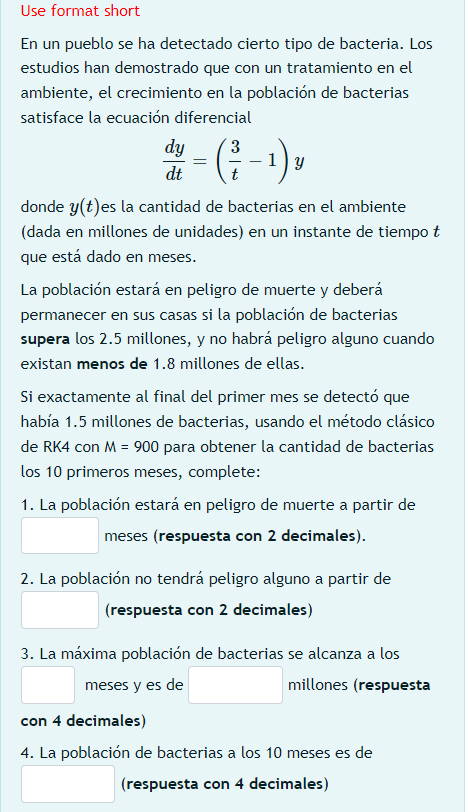

clear
help rk4
f = @(t, y) (3 ./ t - 1) .* y;
a = 1; b = 10; ya = 1.5E6; M = 900;

R = rk4(f, a, b, ya, M);

tiempo = R(:, 1); bacterias = R(:, 2);
bacterias(end) % Punto 4
% Punto 3
maxBacterias = max(bacterias)
tiempo(bacterias == maxBacterias)
tiempoCritico = tiempo(bacterias > 2.5E6); % Tiempos de peligro de muerte
tiempoCritico(1) % Tiempo inicial de cuarentena punto 1
tiempoCritico = tiempo(bacterias < 1.8E6);
tiempoCritico(11)% No hay peligro: punto 2

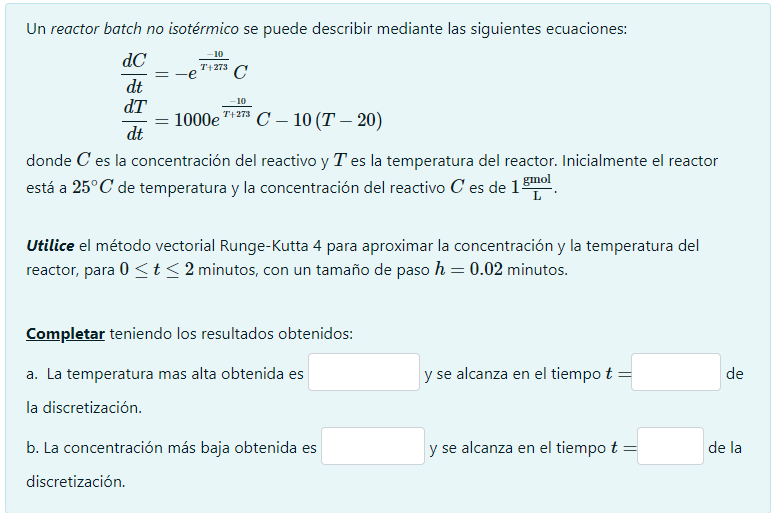

clear
help rks4
F = @(t, U) [-exp(-10./(U(2) + 273)) .* U(1), ...
    1000.*exp(-10./(U(2) + 273)).*U(1) - 10.*(U(2) - 20)]; % U = [C, T]

[t, Z] = rks4(F, 0, 2, [1 25], 2/.02);
C = Z(:, 1); T = Z(:, 2);

% Punto 1:
Tmax = max(T), tmax = t(T == Tmax)
% Punto 2:
Cmin = min(C), tmin = t(C == min(C))

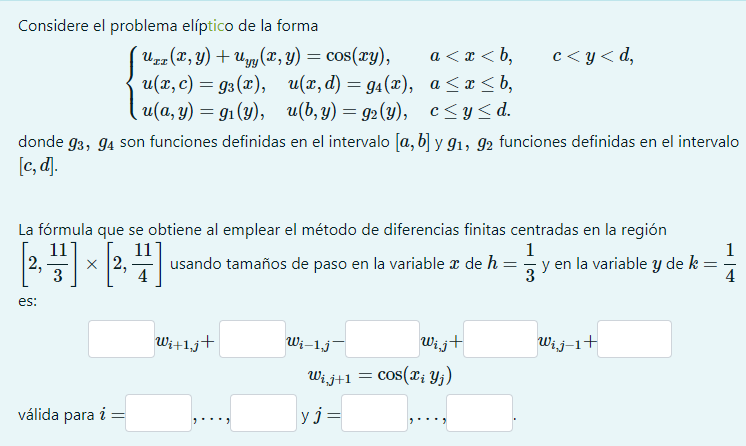   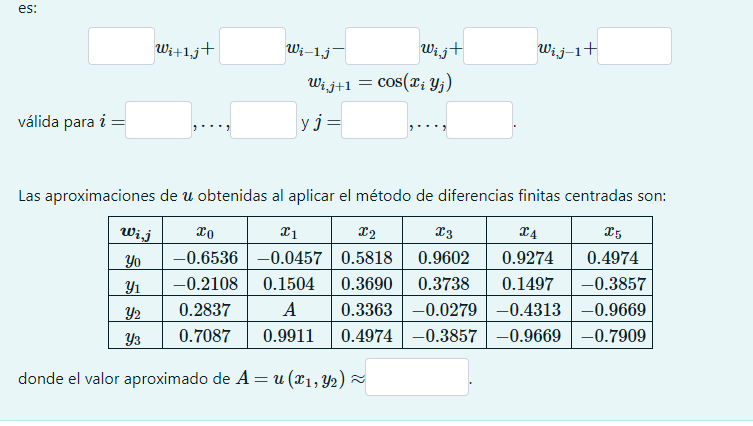

clear
syms omega

N = (11/3 - 2) / (1/3) % Valor N en X
M = (11/4 - 2) / (1/4) % Valor de M en y
Eq = 9*(.3363 + .2837) + 16*(.9911 + .1504) - 50*omega == cos((2 + 1/2) * (2+1/3));
vpasolve(Eq)

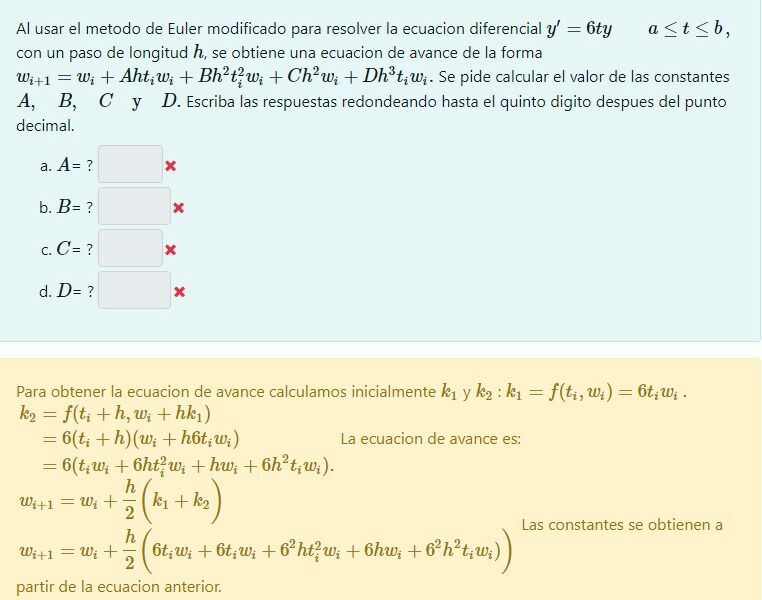

`Ecuación de Avance Euler Modificado`

clear
syms w t h f(t, w)

  Entrada   - f funcion creada con @
            - a y b son los extremos izquierdo y derecho
            - ya es la condicion inicial  y(a)
            - M es el numero de pasos
  Salida    - R = [T', Y'] donde  T  es el vector de abscisas
              y  Y  es el vector de ordenadas




f(t, w) = 6*t*w;
Eq = w + h/2 * (f(t, w) + f(t + h, w + h*f(t, w)))
expand(Eq)

 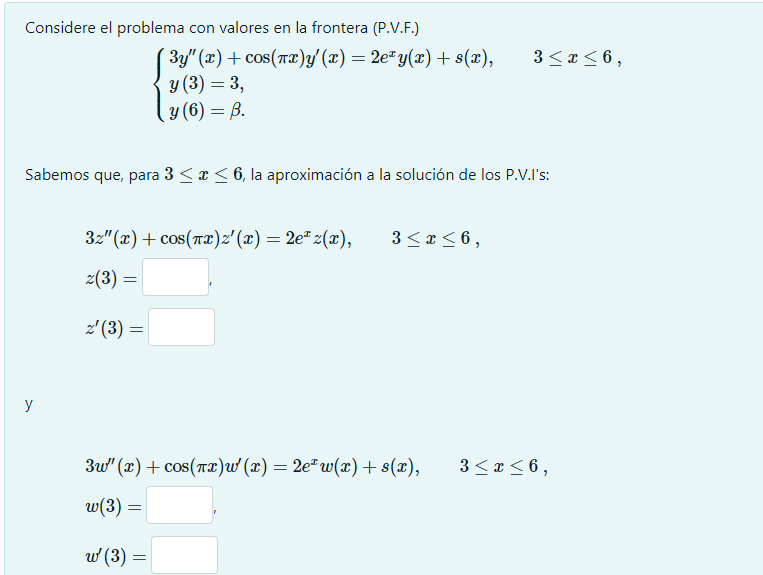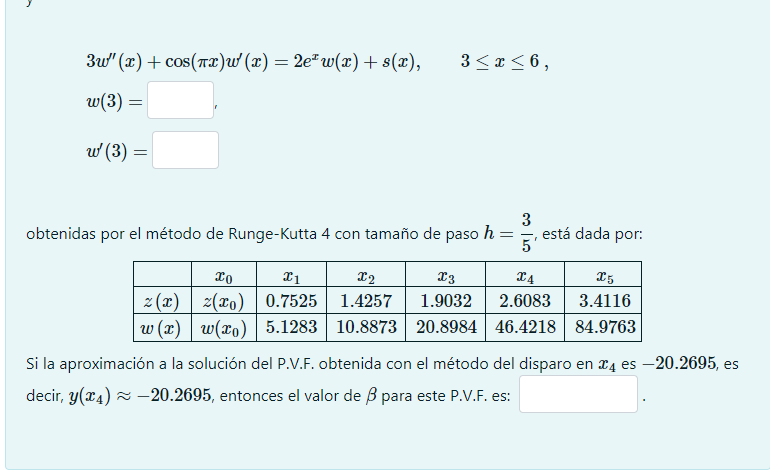

`Ecuación de Avance Euler Modificado`

        

clear


ans = 1.8511e+05

syms beta


maxBacterias = 5.4811e+06

Eq = -20.2695 == 46.4218 + (beta - 84.9763) / 3.4116 * 2.6083;

ans = 3

beta = eval(solve(Eq))

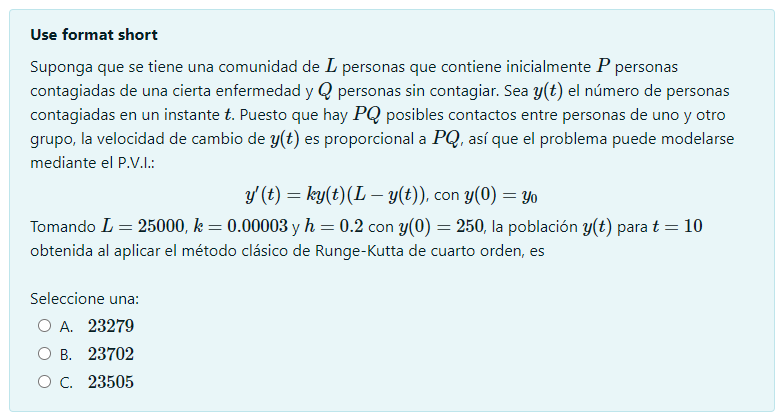

clear

ans = 1.3200


L = 25000; k = 0.00003; ya = 250;

ans = 6.3800

a = 0; b = 100; h = .2; M = (b - a)/h;

f = @(t, y) k*y*(L - y);


  Entrada   - F funcion vectorial creada con @
            - a y b los extremos del intervalo
            - Za = [x1(a), ... , xn(a)] las condiciones iniciales
            - M es el numero de pasos
  Salida    - T es el vector de pasos
            - Z = [x1(t), ... , xn(t)] donde  xk(t)  es la aproximacion a la
              k-esima variable dependiente



R = rk4(f, a, b, ya, M);
R(R == 10,2)

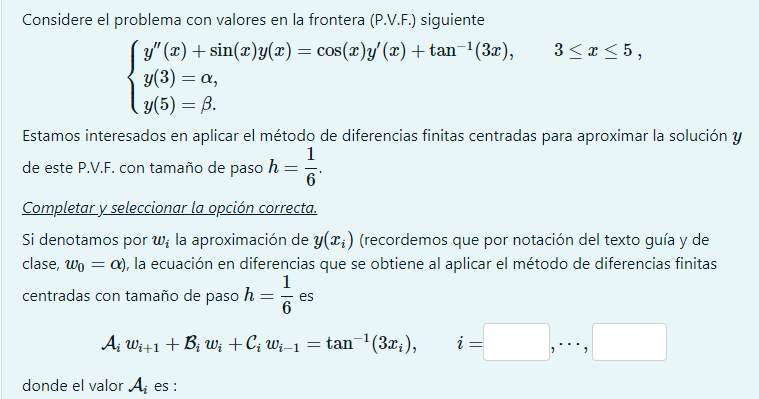

`Ecuación de avance de Diferencias Finitas`

clear
syms x

h = 1/6;
C = (1/h^2 + 1/(2*h) * cos(x) )

Tmax = 96.0565

tmax = 0.2600

A = (1/h^2 - 1/(2*h) *cos(x))
B = (2 / h^2 + -sin(x))

Cmin = 0.1436

tmin = 2

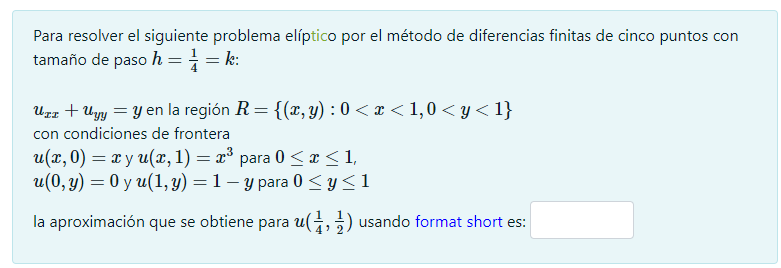

clear
format short

help poisson

N = 5

g = @(x, y) y;

M = 3

f1 = @(x) x;
f2 = @(y) 1 - y;

$$ans = 0.45886977042475426690870676793566$$

f3 = @(x) x.^3;
f4 = @(y) 5*y.^0; % OJO

m = 4 + 1; n = m;

u = poisson(g, f1, f2, f3, f4, 0, 1, 0, 1, m , n)
u(1 +2, 1 +1) % u(y, x) -> u(1/2, 1/4)

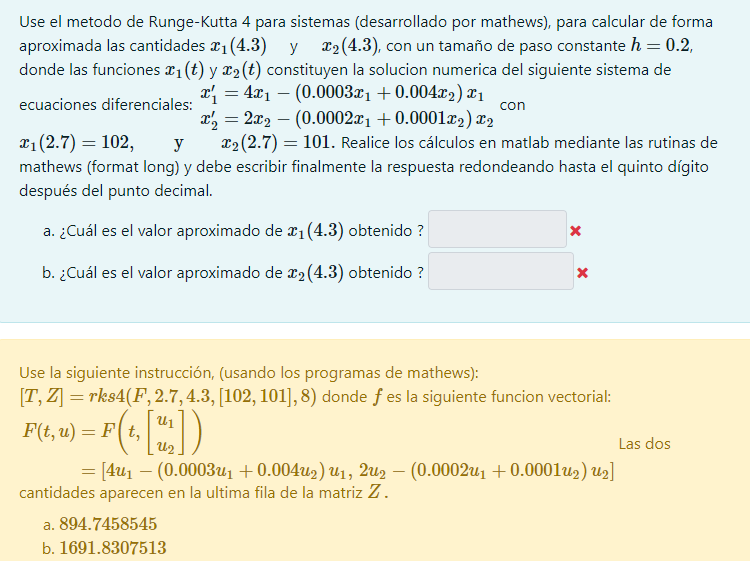

clear
help rks4

$$Eq = w+\frac{h\,\left(6\,\left(h+t\right)\,\left(w+6\,h\,t\,w\right)+6\,t\,w\right)}{2}$$

F = @(t, X) [4*X(1) - (.0003*X(1) + .004*X(2))*X(1), 2*X(2) - (.0002*X(1) + .0001*X(2))*X(2)];

$$ans = 18\,w\,h^{3}\,t+18\,w\,h^{2}\,t^{2}+3\,w\,h^{2}+6\,w\,h\,t+w$$

a = 2.7; b = 4.3; M = round((b - a) / .2); Za = [102, 101];
[T, Z] = rks4(F, a, b, Za, M);
x1 = Z(end, 1), x2 = Z(end, 2)

clear
help rks4
f = @(t, U) [U(2), 9*sin(5*t) - 20*U(2) - 125*U(1)];
[t, R] = rks4(f, 0, 2, [0, 0], 2/.05);
R(t == 2, :)

beta = -2.2545

ans = 2.3702e+04

$$C = 3\,\cos\left(x\right)+36$$

$$A = 36-3\,\cos\left(x\right)$$

$$B = 72-\sin\left(x\right)$$

  poisson.m  -- Resuelve el problema de Poisson u_{xx} + u_{yy} = g(x,y)
  en [a,b] x [c,d], usando el metodo de diferencias finitas de cinco puntos
  g funcion creada con @
  f1 es la condicion de frontera abajo (en y=c) funcion creada con @
  f2 es la condicion de frontera derecha (en x=b) funcion creada con @
  f3 es la condicion de frontera arriba (en y=d) funcion creada con @
  f4 es la condicion de frontera izquierda (en x=a) funcion creada con @
  Las funciones f1, f2, f3 y f4 se ingresan como cadenas de carateres
  m es el numero de puntos sobre el eje x
  n es el numero de puntos sobre el eje y



u =     5.0000    0.2500    0.5000    0.7500    1.0000
    5.0000    2.3239    1.3092    0.9205    0.7500
    5.0000    2.7522    1.5078    0.8884    0.5000
    5.0000    2.2084    1.1127    0.6565    0.2500
    5.0000    0.0156    0.1250    0.4219         0


ans = 2.7522

  Entrada   - F funcion vectorial creada con @
            - a y b los extremos del intervalo
            - Za = [x1(a), ... , xn(a)] las condiciones iniciales
            - M es el numero de pasos
  Salida    - T es el vector de pasos
            - Z = [x1(t), ... , xn(t)] donde  xk(t)  es la aproximacion a la
              k-esima variable dependiente



x1 = 894.7459

x2 = 1.6918e+03

  Entrada   - F funcion vectorial creada con @
            - a y b los extremos del intervalo
            - Za = [x1(a), ... , xn(a)] las condiciones iniciales
            - M es el numero de pasos
  Salida    - T es el vector de pasos
            - Z = [x1(t), ... , xn(t)] donde  xk(t)  es la aproximacion a la
              k-esima variable dependiente



ans =     0.0133   -0.3112
